% Clear Workspace
clear all
clc

% Read STL File
stl1 = stlread("Test Objects\Cylinder.STL");

% Create UniformSliceGeneratorObject
uSGO1 = FlatUniformSliceGenerator(stl1, 10)

uSGO1 =   FlatUniformSliceGenerator with properties:

                 obj: []
    connectivityList: [236×3 double]
       numOfElements: 236
              points: [120×3 int64]
      sliceThickness: 10
           slicePath: [0×3 double]
      slicerAccuracy: 0.0100
           slicerTol: 0.0100



test = uSGO1.slice(10)

test =    50.0000   -5.0000   10.0000
   50.0000   -4.5000   10.0000
   50.0000         0   10.0000
   50.0000    0.5000   10.0000
   50.0000    5.0000   10.0000
   49.9000    5.5000   10.0000
   49.0000   10.0000   10.0000
   48.9000   10.5000   10.0000
   48.0000   15.0000   10.0000
   47.8000   15.5000   10.0000


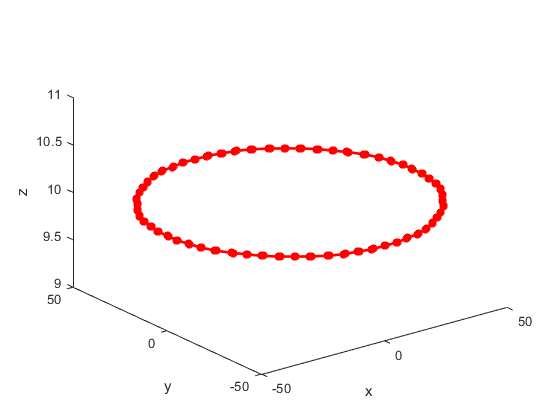

plot3(test(:,1), test(:,2), test(:,3),'-r*','LineWidth',2);
xlabel('x')
ylabel('y')
zlabel('z')


% Generate
figure(3)
uSGO1.generateSlices()

ans =     50    -5     0
    50    -5     0
    50     0     0
    50     0     0
    50     5     0
    50     5     0
    49    10     0
    49    10     0
    48    15     0
    48    15     0


ans =   FlatUniformSliceGenerator with properties:

                 obj: []
    connectivityList: [236×3 double]
       numOfElements: 236
              points: [120×3 int64]
      sliceThickness: 10
           slicePath: [1331×3 double]
      slicerAccuracy: 0.0100
           slicerTol: 0.0100


op = uSGO1.getSlicePath()

op =     50    -5     0
    50    -5     0
    50     0     0
    50     0     0
    50     5     0
    50     5     0
    49    10     0
    49    10     0
    48    15     0
    48    15     0


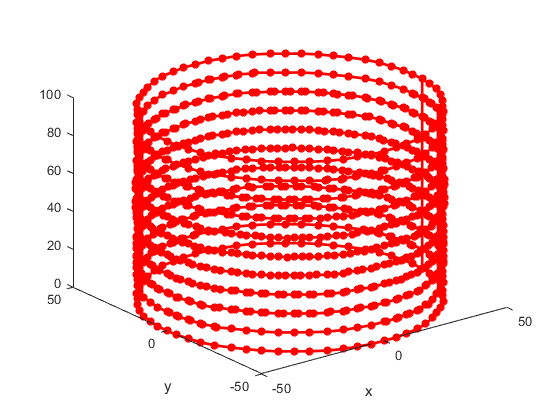


% Show
figure(4)
plot3(op(:,1), op(:,2), op(:,3),'-r*','LineWidth',2);
xlabel('x')
ylabel('y')
view(3);
hold on